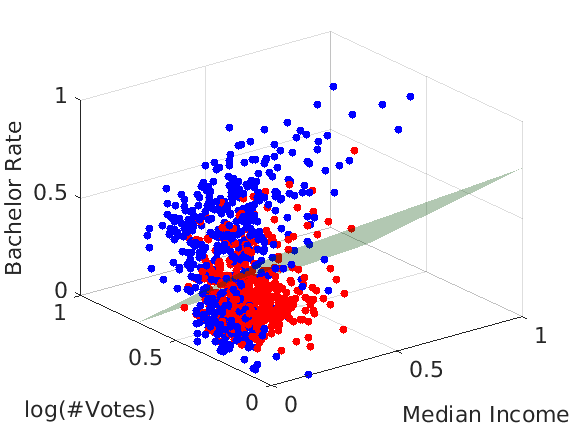

% retrieving data
[out_w, out_b, y, X] = Project1main_q2();

[n,dim] = size(X);
Y = (y*ones(1,dim+1)).*[X ones(n,1)];
w = [out_w; out_b];
lambda = 0.01;
fun = @(I,Y,w)fun0(I,Y,w,lambda);
gfun = @(I,Y,w)gfun0(I,Y,w,lambda);
batch_size = 100;
nsteps = 1000;
nruns = 1000;

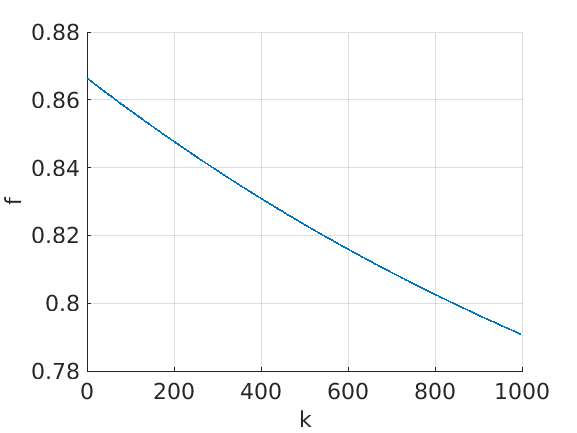

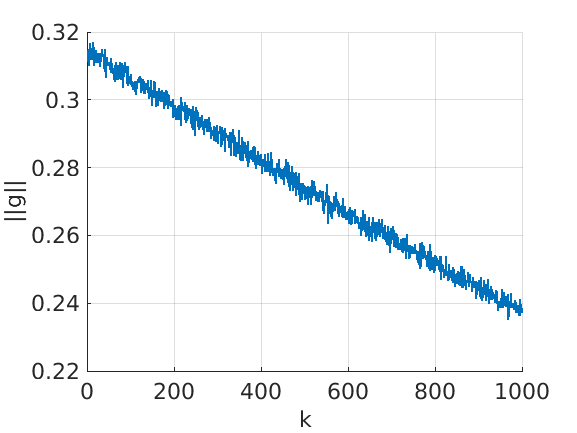

%% alpha-decreasing strategy:
%%% 1. constant
[fs, gs, runtime1] = SG_experiment([0.5;0.5;0.5;0.5],Y,fun,gfun,batch_size,"constant",nsteps,nruns);
SGplotting(fs,gs,'alpha_constant')

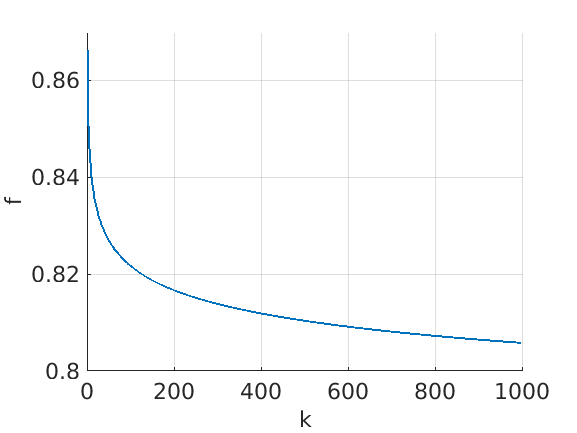

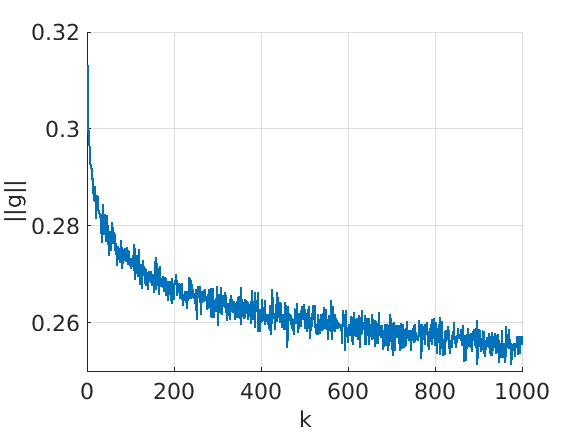

%%% 2. slow decay
[fs, gs, runtime2] = SG_experiment([0.5;0.5;0.5;0.5],Y,fun,gfun,batch_size,"slow",nsteps,nruns);
SGplotting(fs,gs,'alpha_slow')

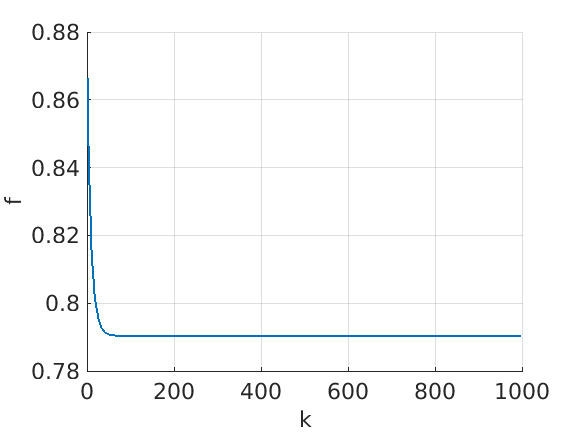

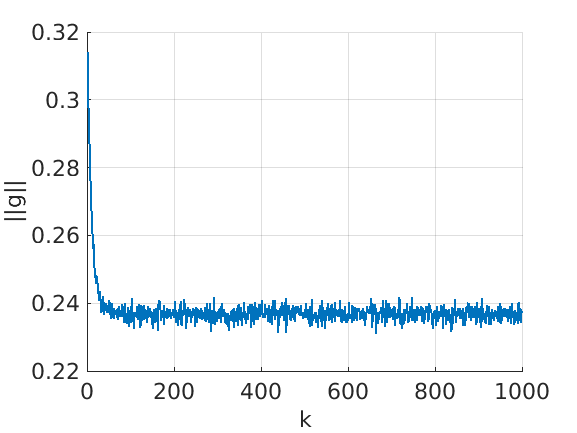

%%% 3. exponential decay
[fs, gs, runtime3] = SG_experiment([0.5;0.5;0.5;0.5],Y,fun,gfun,batch_size,"exponential",nsteps,nruns);
SGplotting(fs,gs,'alpha_exponential')

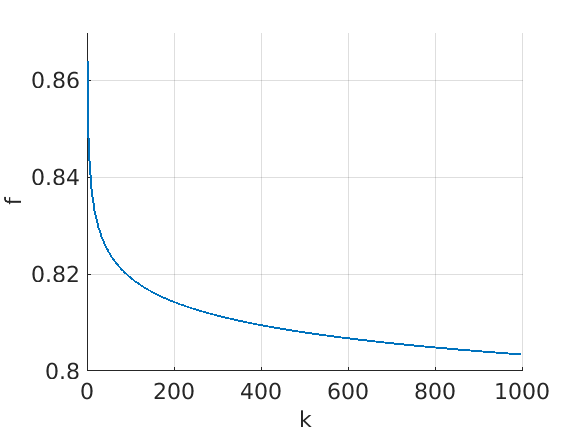

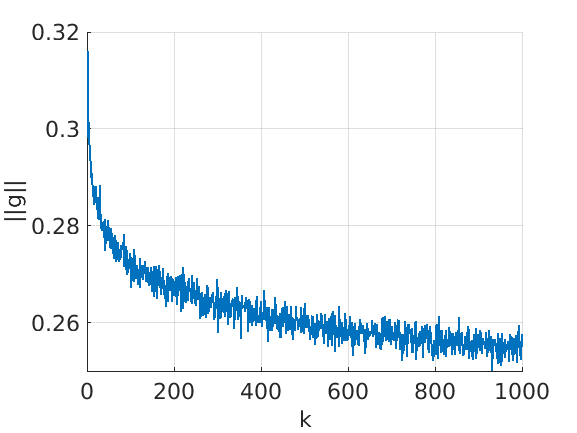

%% batch size:
%%% 1. 100;
batch_size = 100;
[fs, gs, runtime1] = SG_experiment([0.5;0.5;0.5;0.5],Y,fun,gfun,batch_size,"slow",nsteps,nruns);
SGplotting(fs,gs,'batch_100')

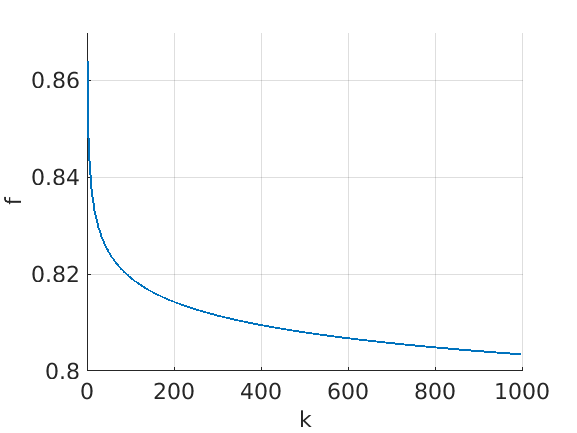

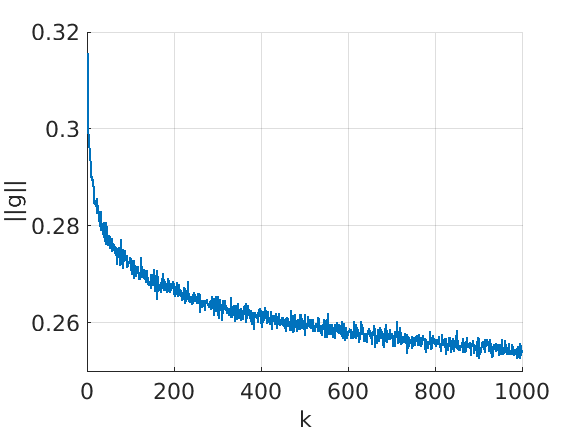

%%% 2. 250;
batch_size = 250;
[fs, gs, runtime2] = SG_experiment([0.5;0.5;0.5;0.5],Y,fun,gfun,batch_size,"slow",nsteps,nruns);
SGplotting(fs,gs,'batch_250')

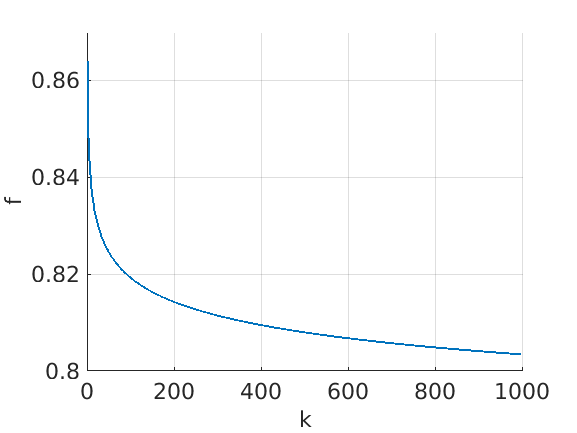

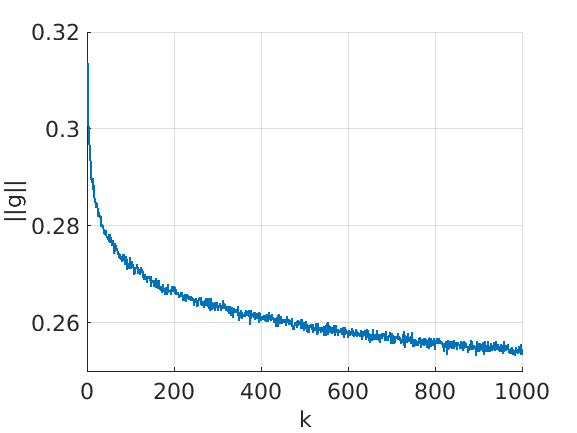

%%% 3. 500;
batch_size = 500;
[fs, gs, runtime3] = SG_experiment([0.5;0.5;0.5;0.5],Y,fun,gfun,batch_size,"slow",nsteps,nruns);
SGplotting(fs,gs,'batch_500')

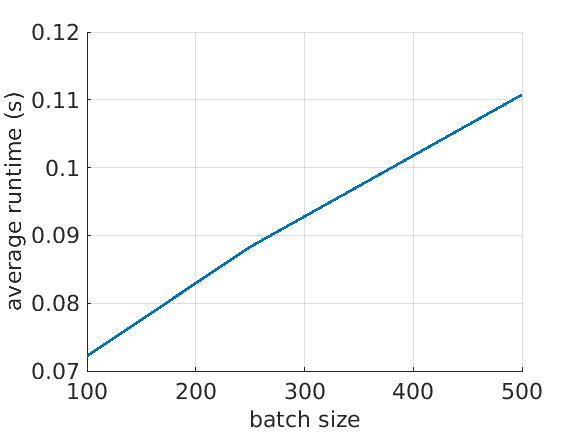

%%% batch size v.s runtime
figure;
hold on;
grid;
plot([100 250 500],[runtime1 runtime2 runtime3],'Linewidth',2);
fsz = 16;
set(gca,'Fontsize',fsz);
xlabel('batch size','Fontsize',fsz);
ylabel('average runtime (s)','Fontsize',fsz);
saveas(gcf, 'sg_runtime.png');

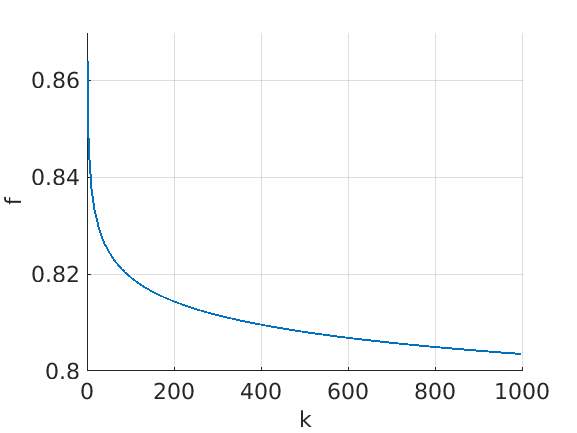

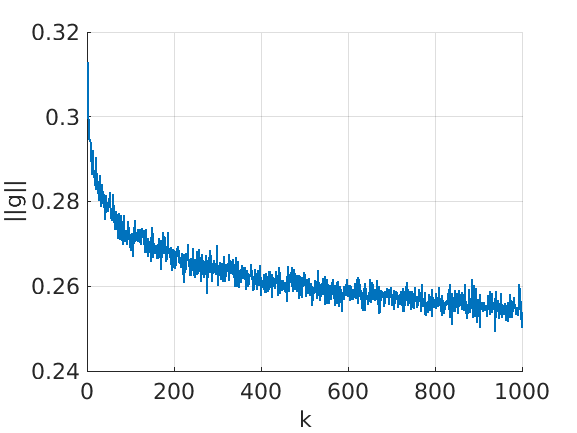

%% lambda:
batch_size = 100;
%%% 1. 0.01;
lambda = 0.01;
fun = @(I,Y,w)fun0(I,Y,w,lambda);
gfun = @(I,Y,w)gfun0(I,Y,w,lambda);
[fs, gs, runtime1] = SG_experiment([0.5;0.5;0.5;0.5],Y,fun,gfun,batch_size,"slow",nsteps,nruns);
SGplotting(fs,gs,'lambda_0.01')

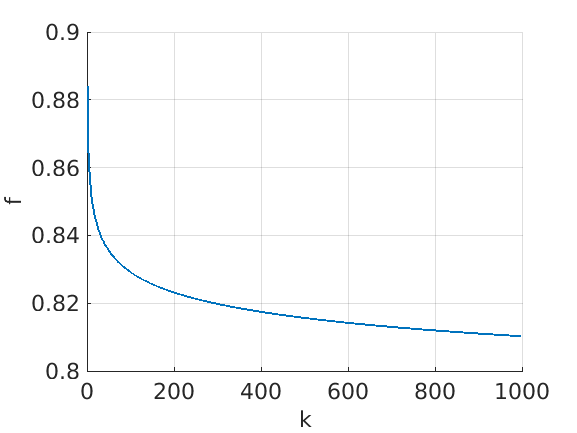

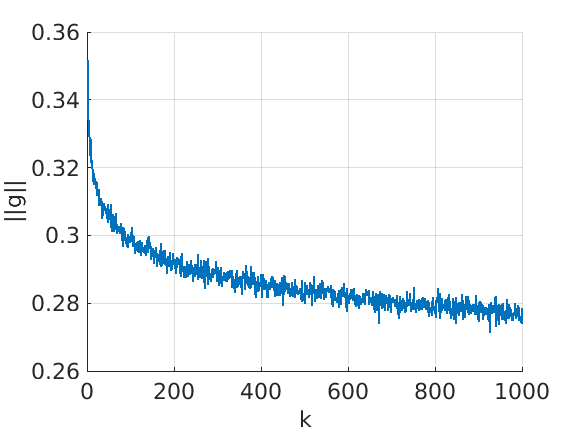

%%% 2. 0.05;
lambda = 0.05;
fun = @(I,Y,w)fun0(I,Y,w,lambda);
gfun = @(I,Y,w)gfun0(I,Y,w,lambda);
[fs, gs, runtime2] = SG_experiment([0.5;0.5;0.5;0.5],Y,fun,gfun,batch_size,"slow",nsteps,nruns);
SGplotting(fs,gs,'lambda_0.05')

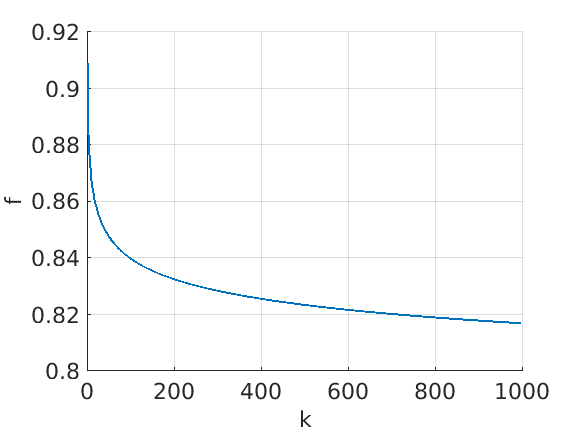

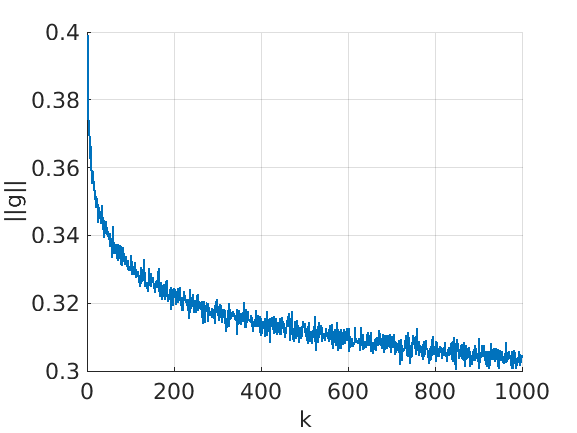

%%% 3. 0.1;
lambda = 0.1;
fun = @(I,Y,w)fun0(I,Y,w,lambda);
gfun = @(I,Y,w)gfun0(I,Y,w,lambda);
[fs, gs, runtime3] = SG_experiment([0.5;0.5;0.5;0.5],Y,fun,gfun,batch_size,"slow",nsteps,nruns);
SGplotting(fs,gs,'lambda_0.1')

function f = fun0(I,Y,w,lam) 
f = sum(log(1 + exp(-Y(I,:)* w)))/length(I) + 0.5*lam* (w'* w);
end

function g = gfun0(I,Y,w,lam) 
aux = exp(-Y(I,:)*w);
d1 = size(Y,2);
g = sum(-Y(I,:).*((aux./(1 + aux))*ones(1,d1)),1)'/length(I) + lam*w;
end